clc
clear

**1:tumor  2: critical organs  3: normal tissue  0: blank**

type_mat = Types;
tumor_ind = find(type_mat==1);
criti_ind = find(type_mat==2);
normal_ind = find(type_mat==3);

dose_mat = DoseMatrix;
AT = dose_mat(tumor_ind,:);
AC = dose_mat(criti_ind,:);
AN = dose_mat(normal_ind,:);

global A
A = [-AT; AC; AN];

[row_at, ~] = size(AT);
atb = -85*ones(row_at, 1);

[row_ac, ~] = size(AC);
acb = 45*ones(row_ac, 1);

[row_an, ~] = size(AN);
anb = 0*ones(row_an, 1);

b = [atb; acb; anb];

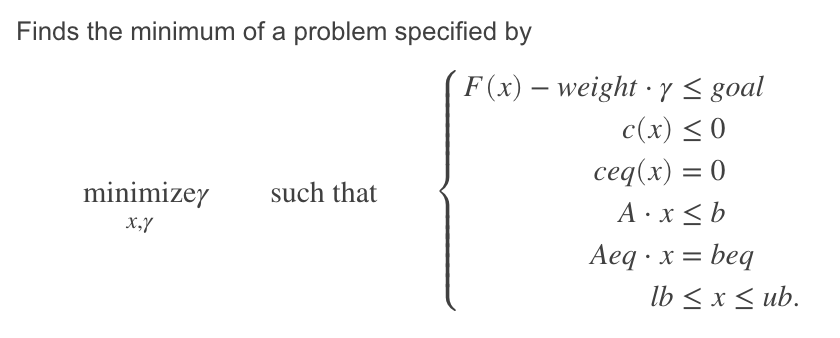

% options = optimoptions(@fgoalattain)
options = optimoptions(@fgoalattain, 'MaxFunctionEvaluations', 40000)

options =   fgoalattain options:

   Set properties:
       MaxFunctionEvaluations: 40000

   Default properties:
          ConstraintTolerance: 1.0000e-06
                      Display: 'final'
            EqualityGoalCount: 0
     FiniteDifferenceStepSize: 'sqrt(eps)'
         FiniteDifferenceType: 'forward'
            FunctionTolerance: 1.0000e-06
                MaxIterations: 400
          OptimalityTolerance: 1.0000e-06
                    OutputFcn: []
                      PlotFcn: []
    SpecifyConstraintGradient: 0
     SpecifyObjectiveGradient: 0
                StepTolerance: 1.0000e-06
                     TypicalX: 'ones(numberOfVariables,1)'
                  UseParallel: 0


weight = [1*ones(1, 9), 1*ones(1, 47), 8*ones(1,999)];

[x, fval] = fgoalattain(@objfun, 5*ones(594, 1), b, weight, [], [], [], [], ...
    zeros(594, 1), [], [], options);


Solver stopped prematurely.

fgoalattain stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 40000 (the selected value).



solu = dose_mat*x;
solu = reshape(solu, 50, 50);
max(max(solu))

ans = 110.3178

solu(20, 29)

ans = 110.0196

 (20, 29)  > 85  

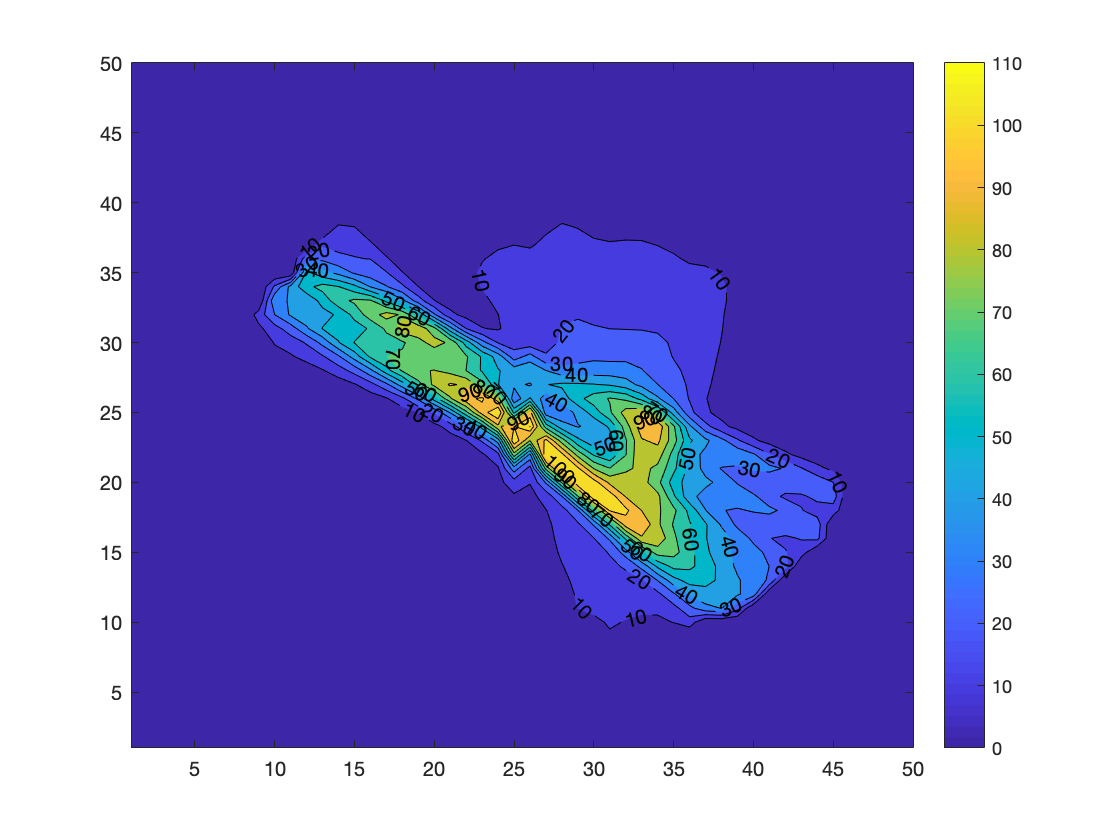

% contourf(50*(type_mat), 4)
% hold on
% contour(solu, 'ShowText','on')
% hold off
contourf(solu, 'ShowText','on')
colorbar

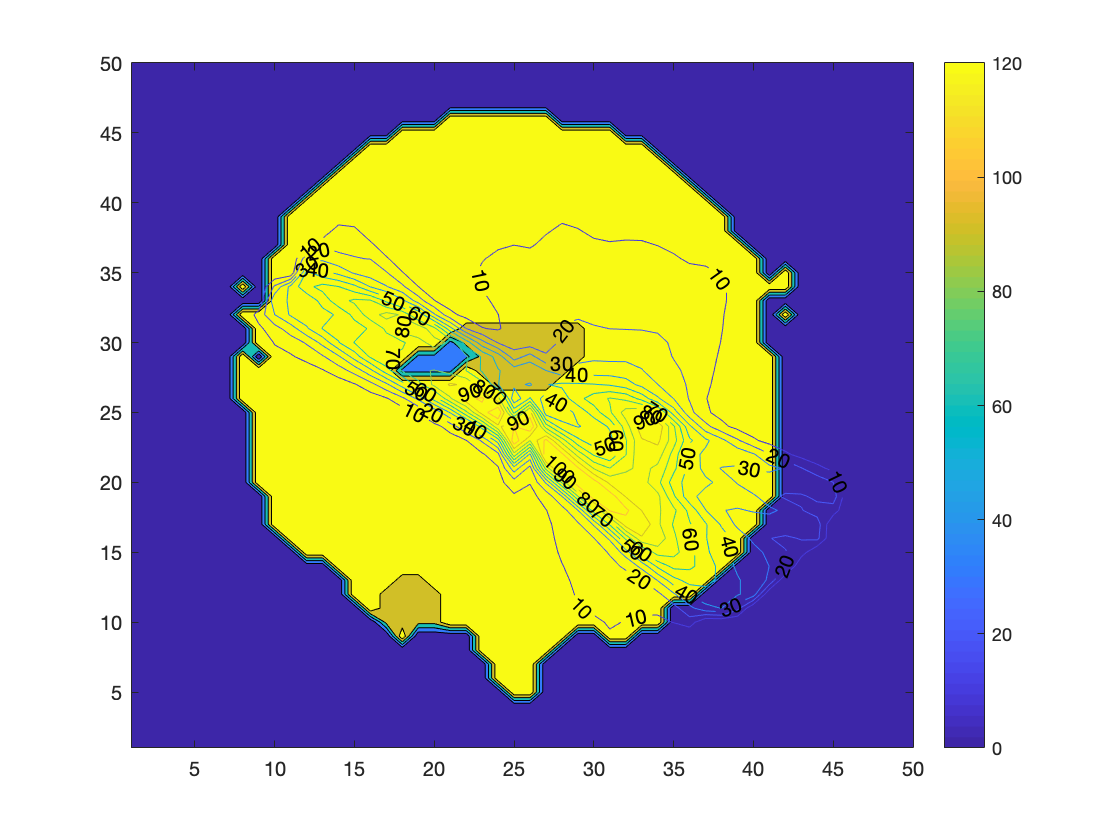

% contourf(50*rot90(type_mat, 2), 4);
contourf(50*(type_mat), 4);
hold on
contour(solu, 'ShowText','on')
colorbar
hold off

contour3(solu, 'ShowText','on')

Undefined function or variable 'solu'.

hold on
% contour(rot90(type_mat, 2))
contour(type_mat)
hold off

colorbar

view([0 90.0])


function [y] = objfun(x)
   global A
   y = A*x;
end